# 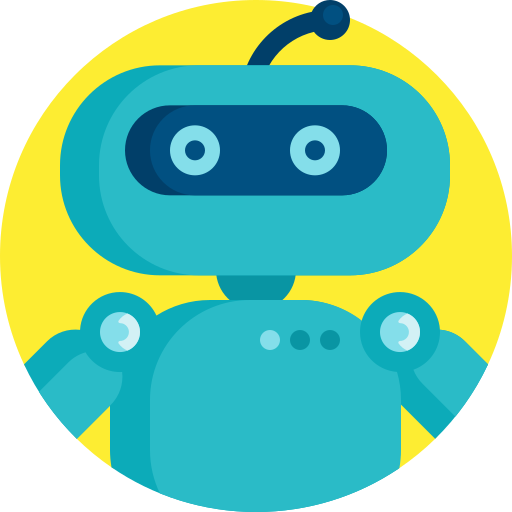

# **MEC4127F: Introduction to Robotics**

# Chapter 11: Position control design for quadcopters

## 11.1 Introduction

In **Chapter 10 ** we were able to design orientation controllers for the roll and pitch channels, and an angular rate controller for the yaw channel. The feedback mechanism for the roll and pitch controllers was predicated on the idea of thrust vectoring, where a desired thrust vector in $\{W\}$ was specified, which inferred the orientation error that could be used by the associated attitude controllers. We can now take the next step and design a feedback controller for the position behaviour of the quadcopter, as well as make use of thrust vectoring to convert information from the outer loop's demands, to the inner loops requirements.

As first introduced in **Chapter 10**,  Figure 11.1 gives a high-level overview of the full control system, which includes the outer loop position controller and inner loop attitude controller.

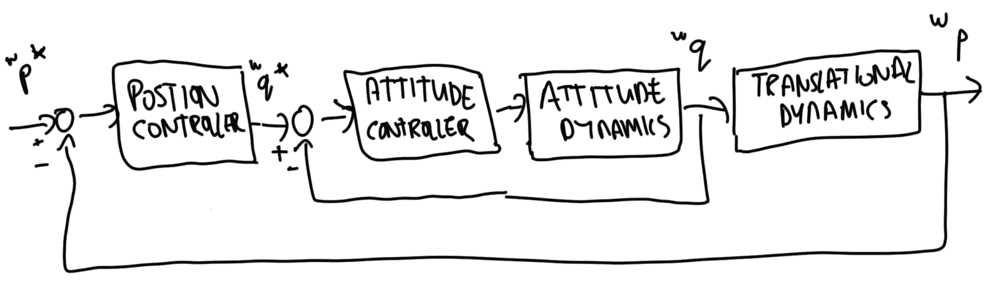

**Figure 11.1:** High-level block diagram of cascaded control scheme.

The main elements that necessitate this scheme are repeated below.

- **control allocation** — mapping desired thrust and torque vectors to the rotor speeds;

- **dynamic analysis** — assessing the dynamics of the system in order to inform an appropriate flight envelope;

- **attitude control design** — design a controller that can stabilise the orientation of the quadcopter whilst also meeting the prescribed specifications;

- **thrust vectoring **— relate the position control command to the orientation error in order to dictate orientation changes required;

- **position control design** — design a controller that can stabilise the translation of the quadcopter whilst also meeting the prescribed specifications;

Points 1-3 were covered in **Chapter 10**, and points 4-5 will be dealt with in this chapter, starting with the formulation of the desired thrust vector based on control action in the translational loop.

## 11.2 Thrust vectoring

### 11.2.1 Recap

As discussed in **Chapter 10**, one can make use of the concept of thrust vectoring to determine the orientation required in order to point $\hat{\bf z}_B$ in a particular direction in $\{W\}$. Because our body-frame thrust vector ${^B{\bf F}}=[0~~0~~f_\Sigma]^T$ is parallel to $\hat{\bf z}_B$, this approach ultimately dictates the direction in $\{W\}$in which our thrust vector points.

Based on **Chapter 9**, we have already shown that the translational dynamics of our quadcopter can be approximated by


$$m{^W\ddot{\bf p}}= {^W{\bf R}_B}{^B{\bf F}+{^W{\bf G},$$


where $m$ is the mass of the quadcopter, $^W\ddot{\bf p}$ is the translational acceleration of the quadcopter in $\{W\}$, ${^W{\bf R}_B}$ is the rotation matrix describing the orientation in $\{W\}$, and ${^W{\bf G}}=[0~~0~~-mg]^T$ is the gravitational force. Noting that ${^W{\bf F}={^W{\bf R}_B}{^B{\bf F}}$, the equation above can also be written as


$$m{^W\ddot{\bf p}}= {^W{\bf F}}+{^W{\bf G}.$$


Considering ${^W{\bf F}={^W{\bf R}_B}{^B{\bf F}}$, with ${^B{\bf F}}=[0~~0~~f_\Sigma]^T$, we are able to directly determine desired values for $f_\Sigma$ based on setting the appropriate rotor speeds:


$$\begin{array}{ll}
f_\Sigma 
&=& \sum_{i=1}^4f_i,\\
&=& k_f\sum_{i=1}^4\overline\omega^2_i.\\
\end{array}$$


Assuming our orientation control design from **Chapter 10** is also effective, we can also dictate how to orient the quadcopter, after some settling period that relates to the bandwidth of our attitude control system. We therefore can think of ${^W{\bf F}^*}$ as a overall control vector from the translational control system, which indicates the desired thrust that is required for a particular translational motion.

### 11.2.2 Feedforward control

If we know the desired acceleration of our quadcopter, namely, ${^W\ddot{\bf p}^*}$, we can solve the translational dynamics equation for ${^W{\bf F}^*}$ based on


$${^W{\bf F}^*}= m{^W\ddot{\bf p}^*}-{^W{\bf G}.$$


The equation above can be thought of as **feedforward control** and describes the *inverse dynamics* of the quadcopter, which relates the desired acceleration to the corresponding desired thrust vector. In theory, if we knew $^W{\bf G}$ and $m$ exactly, if the control allocation mapping from rotor speeds to thrust and torque was exact and instantaneous, and if there were no external disturbances acting on the quadcopter, we could use the approach above to manoeuvre our quadcopter around based on the desired acceleration (which possibly originates from a twice-differentiable trajectory, for example based on **Chapter 7**). The feedforward approach is illustrated in Figure 11.2.

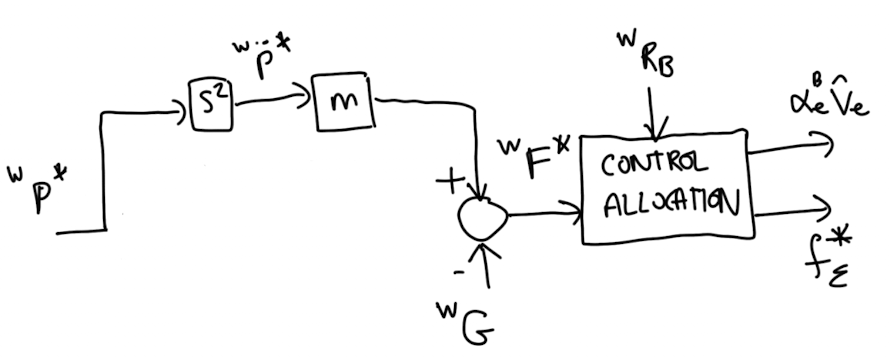

**Figure 11.2:** Block diagram of feedforward control scheme.

The control allocation block is explained in Section 11.2.4.

### 11.2.3 Feedback control

Unfortunately, the assumption that we have perfect knowledge of all system parameters, and that there are no external disturbances acting on the system, is very unrealistic. For this reason, the approach above would not be very reliable. Fortunately, we have a very simple means of accounting for unmodelled dynamics and external dynamics — feedback control! In essence, we can augment the feedforward approach above with feedback control action that is driven by a position error. Assuming a position controller is designed such that the control action is indicated by ${\bf u}_p$, the augmented desired thrust vector in $\{W\}$ is described by


$${^W{\bf F}^*}= m{^W\ddot{\bf p}^*}-{^W{\bf G}+{\bf u}_p.$$


Control action term ${\bf u}_p$ is then responsible for any behaviour that results in ${^W{\bf F}}\neq m{^W\ddot{\bf p}}^*-{^W{\bf G}^*$, such as from aerodynamic drag on the quadcopter body, or wind disturbances. The feedforward-feedback approach is illustrated in Figure 11.3. 

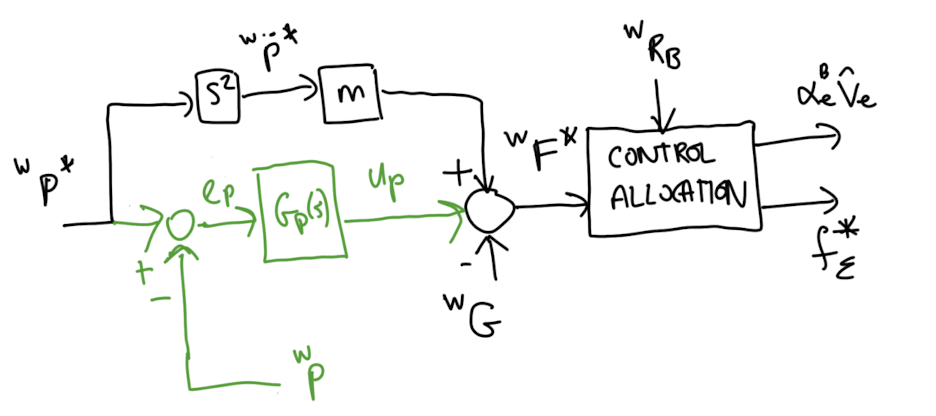

**Figure 11.3:** Block diagram of feedforward-feedback control scheme. 

Note that if the desired acceleration is not known, one can simply set $^W\ddot{\bf p}^*=0$. Control action term ${\bf u}_p$ will be designed in a later section, based on the same frequency domain design principles as used in **Chapter 10**.

### 11.2.4 Control allocation

Once ${^W{\bf F}^*}$ has been determined (be it from Section 11.2.2 or Section 11.2.3) the corresponding desired thrust magnitude and orientation error required must be determined. Recalling that ${^B{\bf F}}=[0~~0~~f_\Sigma]^T$, and noting that rotation matrices preserve the lengths of rotated vectors, it follows that the two-norm (magnitude) of the thrust vector is given by


$$\left|{^W{\bf F}^*}\right|=\left|{^B{\bf F}^*}\right|=f_\Sigma^*,$$


where $f_\Sigma^*\geq 0$ by definition. We therefore have an easy means of determining the amount of net thrust to produce if we know ${^W{\bf F}^*}$. 

Recall from **Chapter 10** that thrust vectoring could be used to determine the orientation error in $\{B\}$ using the mapping


$$\alpha_e{^B\hat{\bf v}}~:~{\hat{\bf z}_B}\rightarrow {^B\hat{\bf z}_D.$$


Physically, ${^W{\bf F}^*}$ represents the *desired* direction and magnitude of $^B{\bf F}$ when described in $\{W\}$. This implies that ${^W{\bf F}^*}$ and ${^W{\bf z}_D={^W{\bf z}_B^*}$ are parallel to each other. By extension, we can determine ${^W{\bf z}_D$, indicating the direction of the frame $\{D\}$ z-axis in $\{W\}$, as


$${^W{\bf z}_D=\frac{^W{\bf F}^*}{\left| ^W{\bf F}^*\right|}=\frac{^W{\bf F}^*}{f_\Sigma^*}.$$


The desired z-axis direction represented in $\{B\}$ follows as


$${^B\hat{\bf z}_D}={^B{\bf R}_W}{^W\hat{\bf z}_D},$$


We can then determine the orientation error, framed as exponential coordinates, as $\alpha_e{^B\hat{\bf v}}$, where


$$\begin{array}{ll}
\alpha_e 
&= \cos^{-1}\left({\hat{\bf z}_B}\cdot {^B\hat{\bf z}_D}\right), 
\end{array}$$



$${^B\hat{\bf v}}=\frac{1}{\sin\alpha_e}{\hat{\bf z}_B}\times {^B\hat{\bf z}_D}.

$$


#### Example: Control allocation

The code block below provides a visualisation of the desired quadcopter orientation as a result of specifying $^W\ddot{\bf p}^*$ and then determining $^W{\bf F}^*$. To simplify things, control action ${\bf u}_p$ is set to zero, which corresponds with the ideal case of having no unmodelled dynamics or disturbances. The desired translational acceleration and current orientation (in quaternion form) are adjustable.

ddP_des = zeros(3,1);
ddP_des(1) =8;
ddP_des(2) =0;
ddP_des(3) =0;

q = zeros(1,4);
q(1) =1;
q(2) =0;
q(3) =0;
q(4) =0.6;
q = q/norm(q);

q =     0.8575         0         0    0.5145


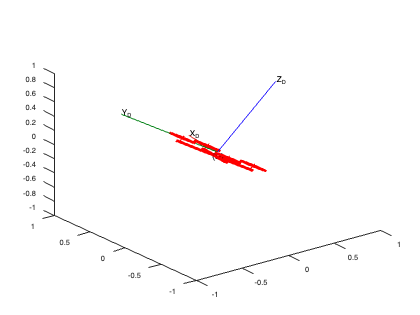


m = 1; g = 9.8;
G = [0 0 -m*g]';
F_des = m*ddP_des-G;

f_sigma = norm(F_des);
R = eye(3);

R = quat2rotm(q);
zb = [0 0 1]';
zd2w = F_des/f_sigma;
zd2b = R'*zd2w;

alpha_e = acos( dot(zb,zd2b) );
if( alpha_e == 0 )
    v_e = [0 0 0]';
else
    v_e = 1/sin(alpha_e)*cross(zb,zd2b);
end

dq = [cos(alpha_e/2) sin(alpha_e/2)*v_e'];
q_des = quatmultiply(q,dq);

figure(1),clf,hold on
% plotTransforms([0 0 0],q,"FrameAxisLabels","on","FrameLabel","W")
plotTransforms([0 0 0],q_des,"MeshFilePath",'multirotor.stl',"MeshColor","red","FrameAxisLabels","on","FrameLabel","D")
xlim([-1 1]),ylim([-1 1]),zlim([-1 1])

## 11.3 Translational open-loop plant model

### 11.3.1 Closed-loop rotational dynamics

Using the content presented in **Chapter 10**, we were able to design feedback controllers for the roll, pitch, and yaw-rate of our attitude system. Using the idea of thrust vectoring, the resulting closed-loop behaviour of the roll and pitch systems will largely dictate the responsiveness of the quadcopter in translational motion. For example, if the roll and pitch controllers are slow in adjusting the orientation of the quadcopter, then by extension, vectoring the thrust on the quadcopter will be equally slow. We therefore want to capture the closed-loop dynamics of the attitude system when designing our position controller, in order to capture the true nature of how translation requires reorienting the quadcopter.

We will assume that the roll and pitch channels are approximately identical, which is a fair assumption when $J_{xx}\approx J_{yy}$ and the feedback control schemes are identical. The roll/pitch loop transfer function is given by 


$$L_o(s)=P_o(s)G_o(s),$$


where $P_o(s)=P_{\Delta\phi}(s)\approx P_{\Delta\theta}(s)$ is the open-loop roll/pitch plant that we introduced in **Chapter 10**, and $G_o(s)=G_{\Delta\phi}(s)=G_{\Delta\theta}(s)$ is the corresponding feedback controller. We can then determine the closed-loop transfer behaviour as


$$T_o(s)=\frac{L_o(s)}{1+L_o(s)},$$


which gives us an indication of how quickly the orientation of the quadcopter can be adjusted using roll/pitch motion when in closed loop, and by extension, how quickly the thrust vector direction can be changed.

### 11.3.2 Thrust vector dynamics

Considering the translational dynamics again of


$$m{^W\ddot{\bf p}}= {^W{\bf F}}+{^W{\bf G},$$


thrust vector ${^W{\bf F}}$ serves as the signal that we ultimately have control over. We can write this thrust vector as


$$\begin{array}{ll}
{^W{\bf F}}
&=&{^W{\bf R}_B}{^B{\bf F}},\\
&=&{^W{\bf R}_B}[0~~0~~f_\Sigma]^T,\\
&=&f_\Sigma{^W{\bf R}_B}[0~~0~~1]^T,\\
&=&f_\Sigma{^W\hat{\bf z}_B}.
\end{array}$$


Recalling that


$$\begin{array}{ll}
f_\Sigma 
&=& f_1+f_2+f_3+f_4,\\
&=& \sum_{i=1}^4f_i,\\
&=& k_f\sum_{i=1}^4\overline\omega^2_i,
\end{array}$$


the desired net thrust, $f_\Sigma^*$ can be related to the achieved net thrust in the Laplace domain based on


$$f_\Sigma(s)=f_\Sigma^*(s)e^{-st_d},$$


where $t_d$ is the delay period resulting from the motor speed delay from


$$\overline\omega_i(s)=\overline\omega_i^*(s)e^{-st_d}.$$


Vector ${^W\hat{\bf z}_B}={^W{\bf R}_B}{\hat{\bf z}_B}$, representing $\hat{\bf z}_B$ when described in $\{W\}$, encodes the closed-loop roll/pitch behaviour of the quadcopter and can therefore be related to the desired vector using

 
$${^W\hat{\bf z}_B}(s)=T_o(s){^W\hat{\bf z}^*_B}(s),$$


where $T_o(s)$ describes the closed-loop roll/pitch transfer behaviour. In other words, the closed-loop roll/pitch behaviour dictates how quickly the quadcopter can reorient $\hat{\bf z}_B$ in $\{W\}$. Using the information above, ${^W{\bf F}}$ can be described by in the Laplace domain as


$$\begin{array}{ll}
{^W{\bf F}}(s)
&=&f_\Sigma(s){^W\hat{\bf z}_B}(s),\\
&=&f_\Sigma^*(s)T_o(s){^W{\bf z}^*_B}(s)e^{-st_d},\\
&=&T_o(s){^W{\bf F}^*}(s)e^{-st_d},
\end{array}

$$


where ${^W{\bf F}^*}(s)=f_\Sigma^*(s){^W{\bf z}^*_B}(s)$ by definition.

Assuming that the gravitational force has been approximately compensated for using feedforward based on


$${^W{\bf F}^*}= -{^W{\bf G}+{\bf u}_p,$$


and setting $m{^W\ddot{\bf p}^*}=0$ for now, the translational dynamics of the quadcopter, stemming from the dynamic equation of $m{^W\ddot{\bf p}}= {^W{\bf F}}+{^W{\bf G}\approx {^W{\bf F}},$ can be represented in transfer function form as

${{\bf p}(s)}=\frac{1}{ms^2}{^W{\bf F}}(s)$.

We can then relate the desired thrust vector to the actual thrust vector, which yields


$$\begin{array}{ll}
{{\bf p}(s)}
&=&\frac{1}{ms^2}{^W{\bf F}}(s),\\
&=&\frac{T_o(s)e^{-st_d}}{ms^2}{^W{\bf F}^*}(s).

\end{array}$$


The transfer function


$$P_t(s)=\frac{T_o(s)e^{-st_d}}{ms^2}$$


describes the open-loop plant model relating the desired thrust vector to the dynamic position of the quadcopter in 3D space. We can therefore use this model when designing our translational controllers if we know $T_o(s)$, $m$, and $t_d$. 

Note that the result is somewhat conservative under certain motions. Specifically, if motion is to take place along ${^W\hat{\bf z}_B}$, in other words, parallel to the thrust vector, then the dynamics associated with adjusting the thrust vector — $T_o(s)$ — do not actually come into play. That being said, general quadcopter motion of interest usually involves reorienting the platform, which is correctly governed by the equation above.

## 11.4 Translational control design

The information obtained in Section 11.3 can be used to design controllers for motion in 3D space. Given that the transfer behaviour from desired thrust vector to position in $\{W\}$ is given by


$$\begin{array}{ll}
{{\bf p}(s)}
&=&\frac{T_o(s)e^{-st_d}}{ms^2}{^W{\bf F}^*}(s),

\end{array}$$


which possesses two integrators, a delay term, and additional phase lag from $T_o(s)$, derivative action is required in the position controller to stabilise the closed-loop position system. As with the attitude dynamics, if there are no external disturbances acting on the position system, we can get away with designing a PD controller. If, however, our quadcopter encounters real-world disturbances, such as aerodynamic drag on the body or wind forces, we would need integral action in the form of a PID controller. Assuming the more realistic latter case, we can implement a PID controller of the form

$G_t(s)=K\frac{\left(1+s/\alpha\right)\left(1+T_is\right)}{sT_i\left(1+s/\beta\right)}$,

where $\alpha$ and $\beta$ is the zero and pole of $G_t(s)$, respectively, $T_i$ is integral time constant, and$K$ is a gain applied at all frequencies. As with the attitude control design, we can first design the PID controller as if it is a PD controller, after setting $T_i\gg K$, and then subsequently reduce $T_i$ as far as allowed by the stability boundaries after satisfying the design requirements.

#### Example: translational control design

We will use the attitude system parameters from the examples in **Chapter 10** to determine the closed-loop rotational system, $T_o(s)$. Our roll/pitch open-loop plant was given by


$$P_{o}(s)=\frac{1}{J_{xx}s^2}=\frac{1000}{s^2}e^{-st_d},$$


and the designed feedback PID controller was given by


$$\begin{array}{ll}
G_{o}(s)
&=&K\frac{\left(1+s/\alpha\right)}{\left(1+s/\beta\right)}\frac{\left(1+T_is\right)}{T_is},\\
&=&0.005\frac{\left(1+s/0.325\right)}{\left(1+s/42.44\right)}\frac{\left(1+5s\right)}{5s}.
\end{array}$$


The closed-loop transfer function follows as


$$\begin{array}{ll}
T_o(s)
&=&\frac{P_o(s)G_o(s)}{1+P_o(s)G_o(s)}.
\end{array}$$


s = tf('s');
Jxx = 1e-3;
Po = 1/(Jxx*s^2)*exp(-s*.01);
Go = .005*(1+s/0.325)/(1+s/42.44)*(1+5*s)/(5*s)


Go =
 
  1.061 s^2 + 0.557 s + 0.06896
  -----------------------------
       1.625 s^2 + 68.97 s
 
Continuous-time transfer function.
Model Properties


To = feedback(Po*Go,1)


To =
 
  A = 
           x1      x2      x3      x4
   x1  -42.44  -652.9  -342.8  -42.44
   x2       1       0       0       0
   x3       0       1       0       0
   x4       0       0       1       0
 
  B = 
       u1
   x1  32
   x2   0
   x3   0
   x4   0
 
  C = 
          x1     x2     x3     x4
   y1      0   20.4  10.71  1.326
 
  D = 
       u1
   y1   0
 
  (values computed with all internal delays set to zero)

  Internal delays (seconds): 0.01 
 
Continuous-time state-space model.


Using this information, we can form the open-loop translational plant


$$P_t(s)=\frac{T_o(s)e^{-st_d}}{ms^2},$$


which will be used for our design of each translational channel.

m = 1;
P = To/m/(s^2)*exp(-s*.01);

The outer loop bandwidth needs to be lower than the inner loop, as the position behaviour relies on the attitude behaviour to settle before achieving the desired motion. We will therefore set the bandwidth of the outer loop to be sufficiently small relative to that of the inner loop. The desired specifications follow as

- a desired $2\%$ settling time requirement of $T_s=4$ seconds (four times that of the inner loop) and, 

- an allowed percentage overshoot of $\%OS=15\%$.

This results in the following design requirements:


$$\zeta=\frac{-\ln(\%OS/100)}{\sqrt{\pi^2+\ln^2(\%OS/100)}}=0.5912,$$



$$M_A=\frac{1}{2\zeta\sqrt{1-\zeta^2}}=1.0487.$$


$\omega_p=\omega_n\sqrt{1-2\zeta^2}=\frac{4}{\zeta T_s}\sqrt{1-2\zeta^2}=1.32$ rad/s.

Ts = 4;
OS = 15;
zeta = -log(OS/100)/sqrt( pi^2+log(OS/100)^2 );
wn = 4/zeta/Ts;
wp = wn*sqrt(1-2*zeta^2);

Ma = 1/( 2*zeta*sqrt(1-zeta^2) ); %overbound
Mb = .98; %underbound

According to the design methodology detailed in Section 10.4.3, we first set $T_i \gg K$ and then design the feedback controller as if its a PD controller. Design of the PD controller requires us to first set $\alpha=\beta$ and set $K=1$, followed by choosing $\alpha$ based on the desired phase lead at the chosen frequency design point. Once $\alpha$ is chosen, $\beta$ is determined algebraically. Finally, $K$ can be readjusted as required.

The code block below allows for design of the PID controller, as well as the necessary visualisation for purposes of synthesis. We start by setting:

- 
$$K=1$$


- $\alpha=\beta=1$.

- $T_i=100$.

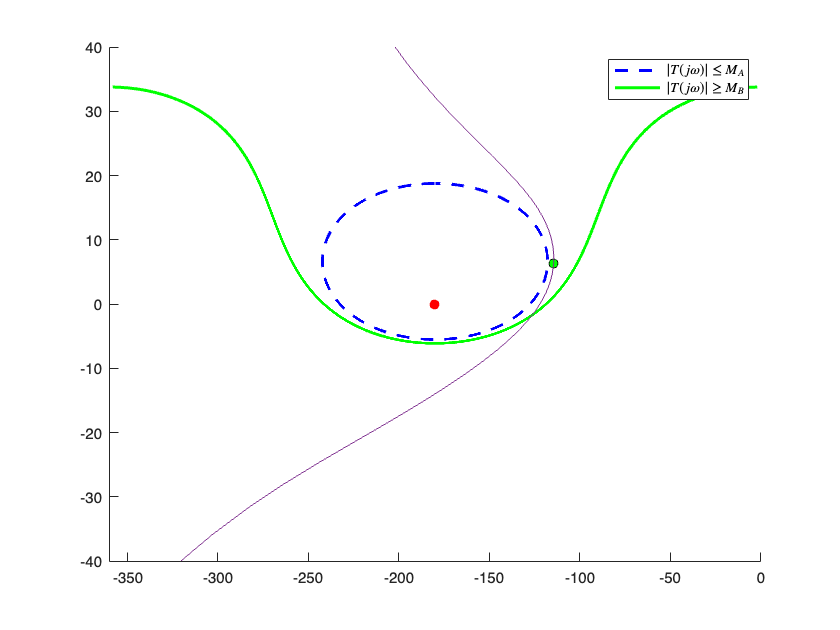

K = 0.45;
alpha = 0.17;
beta = 10;
Ti =10;

G = K*(1+s/alpha)/(1+s/beta)*(1+Ti*s)/(Ti*s);
L = P*G;

figure(1),clf,hold on

M = [Ma Mb];
for k = 1:length(M)
    phi = linspace(0,2*pi,1e4);
    c = -1;
    r = 1/M(k);
    K = c + r*exp(1i*phi);

    mag_K = 20*log10( abs(K) );
    phi_K = angle( K )*180/pi;
    for i=1:length(phi_K)
        if( phi_K(i) > 0), phi_K(i) = phi_K(i)-360; end
    end

    if( k==1 )
        plot( phi_K(2:end-1),-mag_K(2:end-1),'--b',LineWidth=2 )
    else
        plot( phi_K(2:end-1),-mag_K(2:end-1),'-g',LineWidth=2 )
        Lw = squeeze( freqresp(L,wp) );
        ang_Lw = angle(Lw)*180/pi;
        if( ang_Lw > 0 )
            ang_Lw = ang_Lw-360;
        end
        plot(ang_Lw,20*log10(abs(Lw)),'o',MarkerFaceColor='g',MarkerEdgeColor='k')
    end
end

[mag,phase] = nichols(L);
for i=1:length(phase)
    if( phase(i) > 0 )
        phase(i) = phase(i)-360;
    end
end
plot(squeeze(phase),squeeze(20*log10(mag)))
plot(-180,0,'ro',MarkerFaceColor='r')
legend('$|T(j\omega)|\leq M_A$','$|T(j\omega)|\geq M_B$',Interpreter="latex")
xlim([-360,0]),ylim([-40,40])

We see that we are currently not meeting either design requirement, as expected. We therefore must choose a design frequency point where we are going to add the most phase, as well as the phase required at that design point. By inspection, we need approximately $75^\circ$ of phase lead to try avoid the stability boundary. Using $\omega_{max}=\omega_p=1.32$ rad/s, we can then determine the required zero and pole locations of our controller using

$\alpha=\frac{\omega_{max}}{\tan\left(\frac{\phi_{max}+\pi/2}{2}\right)}$,

and

$\beta=\frac{\omega_{max}^2}{\alpha}$.

w_max = wp;
phi_max = 75*pi/180;
alpha = w_max/tan( (phi_max+pi/2)/2 )

alpha = 0.1738

beta = w_max^2/alpha

beta = 10.0260

This yields the PD parameters of $\{\alpha,\beta\}=\{0.174,10.02\}$ rad/s. Updating our simulation code block above shows that we have provided sufficient phase at the design frequency but now have too much gain. We therefore reduce the gain to $K=0.45$, which meets both design requirements. 

The final step is to reduce $T_i$ as far as possible. A value of $T_i=10$ is close to as small as we can go before hitting the stability limit. 

Checking the time-domain step response shows that we meet both user specifications in the time domain too.

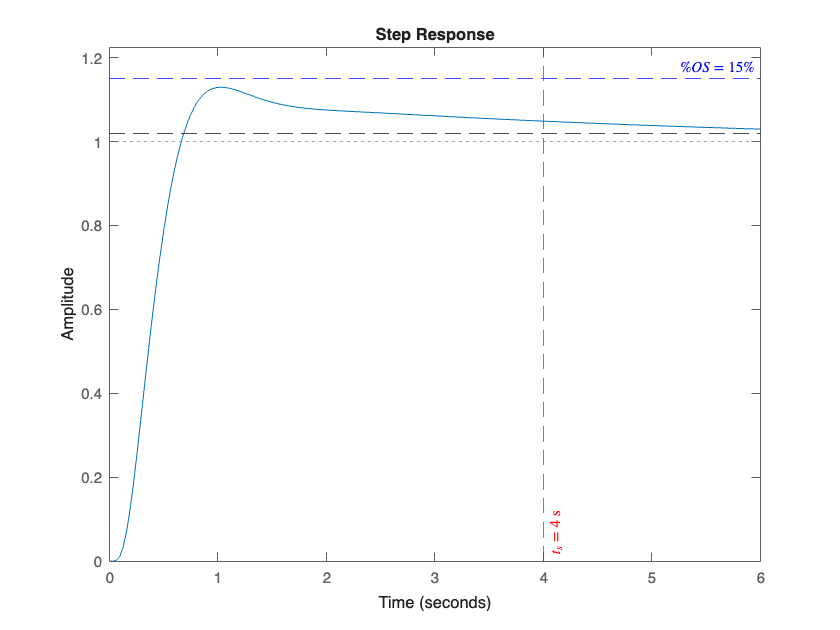

T = feedback(L,1);
figure, hold on
step(T,Ts+2)
yline(1+OS/100,'--b',['$\% OS=$',num2str(OS),'$\%$'],'Interpreter','latex')
yline(1+0.02,'--k')
xline(Ts,'--r',['$t_s=$',num2str(Ts),' s'],'Interpreter','latex','LabelVerticalAlignment','bottom')
ylim([0 1+1.5*OS/100])

Our designed PID controller, which is applicable to all three translational channels, is given by


$$\begin{array}{ll}
G_{p}(s)
&=&K\frac{\left(1+s/\alpha\right)}{\left(1+s/\beta\right)}\frac{\left(1+T_is\right)}{T_is},\\
&=&0.45\frac{\left(1+s/0.17\right)}{\left(1+s/10\right)}\frac{\left(1+10s\right)}{10s}.
\end{array}$$


Note that in certain cases when designing a PID controller, we may need to update the $\{K,\alpha,\beta\}$ values after choosing $T_i$, as well as the peak frequency value (where the largest phase lead is applied).  

## 11.5 Implementation of control scheme

The code block below provides a nonlinear 3D closed-loop simulation of the quadcopter's attitude and translational using the controllers that were designed in the preceding examples. The controllers are implemented using pseudo-continuous-time difference equations.

%system parameters
Jxx = 1e-3;
Jyy = 1e-3;
Jzz = 2e-3;
J = diag( [Jxx,Jyy,Jzz] );
mass = 1; 
g = 9.8;
dT = 0.01;

%initial conditions
w = [0 0 0]';
q = [1 0 0 0];

e_or_past = zeros(3,1);
u_or_past = zeros(3,1);
desiredMotorSpeeds_past = zeros(4,1);
du_or = zeros(3,1);
de_or = zeros(3,1);
w_dot = zeros(3,1);
de_or_past = zeros(3,1);
u_or = zeros(3,1);
ddu_or = zeros(3,1);

du_p = zeros(3,1);
u_p = zeros(3,1);
e_p_past = zeros(3,1);
de_p_past = zeros(3,1);

kf = 1e-5;
kt = 1e-8;
l = 0.1;

A = [kf    kf   kf   kf;
     0  -l*kf    0 l*kf;
     -l*kf  0 l*kf    0;
     kt   -kt   kt  -kt];

invA = inv(A);

q_array = [];
p_array = [];
z_des_array = [];
time = [];

Gw = [0 0 -mass*g]';
p = zeros(3,1);
dp = zeros(3,1);

Fb = [0 0 0]';
p_des = [0.1 0.1 0.1]';

simTime = 5;

for i=1:simTime/dT
    %position controller
    e_p = p_des - p;

    de_p = (e_p-e_p_past)/dT;
    dde_p = (de_p-de_p_past)/dT;

    Ti = 10;
    K = 0.45;
    alpha = 0.17;
    beta = 10;

    ddu_p = (-Ti*du_p + K*e_p + K*(1/alpha+Ti)*de_p + K*Ti/alpha*dde_p)/(Ti/beta);
    du_p = du_p + dT*ddu_p;
    u_p = u_p + dT*du_p;

    %thrust vectoring
    F_des = u_p-Gw;
    f_sigma_des = norm(F_des);
    z_des = F_des/f_sigma_des;

    %orientation error
    R = quat2rotm(q);
    zb = [0 0 1]';
    zd2b = R'*z_des;
    alpha_e = acos( dot(zb,zd2b) ); 
    if (alpha_e==0)
        v_e = [0 0 0]';
    else
        v_e = cross(zb,zd2b)/sin(alpha_e); 
    end
    e_or = alpha_e * v_e;

    %derivatives
    de_or = (e_or-e_or_past)/dT;
    dde_or = (de_or-de_or_past)/dT;

    %roll/pitch PID controller
    Ti = 5;
    K = 0.005;
    alpha = 0.325;
    beta = 42;

    ddu_or(1:2) = (-Ti*du_or(1:2) + K*e_or(1:2)+K*(1/alpha+Ti)*de_or(1:2)+K*Ti/alpha*dde_or(1:2))/(Ti/beta);
    du_or(1:2) = du_or(1:2) + dT*ddu_or(1:2);
    u_or(1:2) = u_or(1:2) + dT*du_or(1:2);

    %yaw PI controller
    K = 0.06;
    Ti = 0.8;

    du_or(3) = K/Ti*(-w(3))+K*(-w_dot(3));
    u_or(3) = u_or(3)+dT*du_or(3);

    %control allocation
    desiredMotorSpeeds = invA*[f_sigma_des; u_or];
    %motor dynamics
    motorSpeeds = desiredMotorSpeeds_past;
    % motorSpeeds = desiredMotorSpeeds;

    %rotational dynamics
    m = A(2:4,:)*motorSpeeds;
    w_dot = J\( m-cross(w,J*w) );
    w = w+dT*w_dot;

    alpha = norm(w)*dT;
    if( alpha==0 )
        v = [0 0 0]';
    else
        v = w/norm(w);
    end
    dq = [cos(alpha/2) sin(alpha/2)*v'];
    q = quatmultiply(q,dq);
    q = q/norm(q);

    %translational dynamics
    Fb(3) = A(1,:)*motorSpeeds;
    R = quat2rotm(q);
    ddp = 1/mass*( R*Fb+Gw );
    dp = dp + dT*ddp;
    p = p + dT*dp;

    %update past state
    e_or_past = e_or;
    de_or_past = de_or;

    de_p_past = de_p;
    e_p_past = e_p;

    desiredMotorSpeeds_past = desiredMotorSpeeds;

    %plotting
    % if( mod(i,5)==0 )
    %     figure(1),clf
    %     plotTransforms([0 0 0],q,"MeshFilePath",'multirotor.stl',"MeshColor","red","FrameAxisLabels","on","FrameLabel","B")
    %     xlim([-2 2]),ylim([-2 2]),zlim([-1 3])
    %     drawnow
    % end

    q_array = [q_array; q];
    z_des_array = [z_des_array z_des];
    p_array = [p_array p];
    time = [time dT*i];
end

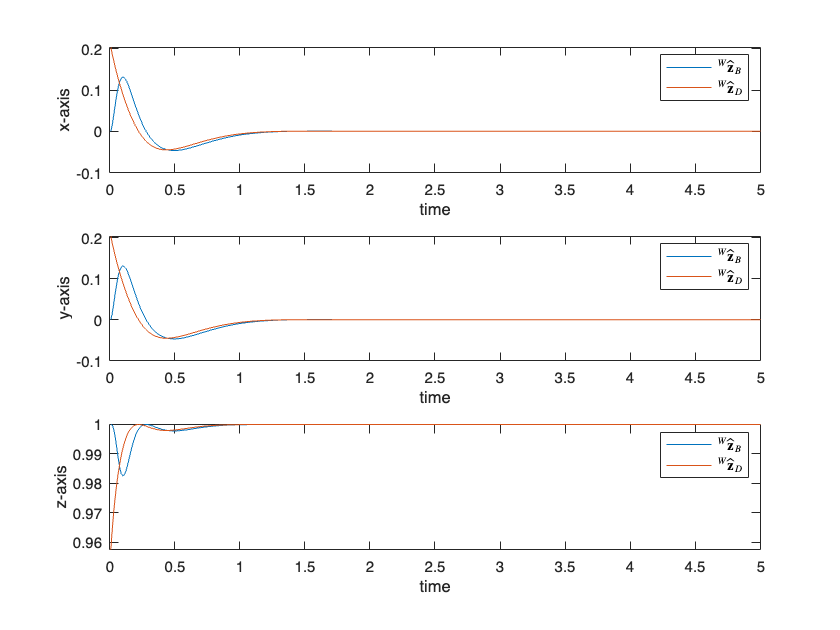

%determine zb wrt {w} and zd wrt {w}
z_b2w = quatrotate(quatconj(q_array),[0 0 1]);
%plots
figure(2),clf
subplot(3,1,1),plot(time,z_b2w(:,1)),hold on, plot(time,z_des_array(1,:))
xlabel('time'),ylabel('x-axis'),legend('${^W\hat{\bf z}_B}$','${^W\hat{\bf z}_D}$',"interpreter","latex")
subplot(3,1,2),plot(time,z_b2w(:,2)),hold on, plot(time,z_des_array(2,:))
xlabel('time'),ylabel('y-axis'),legend('${^W\hat{\bf z}_B}$','${^W\hat{\bf z}_D}$',"interpreter","latex")
subplot(3,1,3),plot(time,z_b2w(:,3)),hold on, plot(time,z_des_array(3,:))
xlabel('time'),ylabel('z-axis'),legend('${^W\hat{\bf z}_B}$','${^W\hat{\bf z}_D}$',"interpreter","latex")

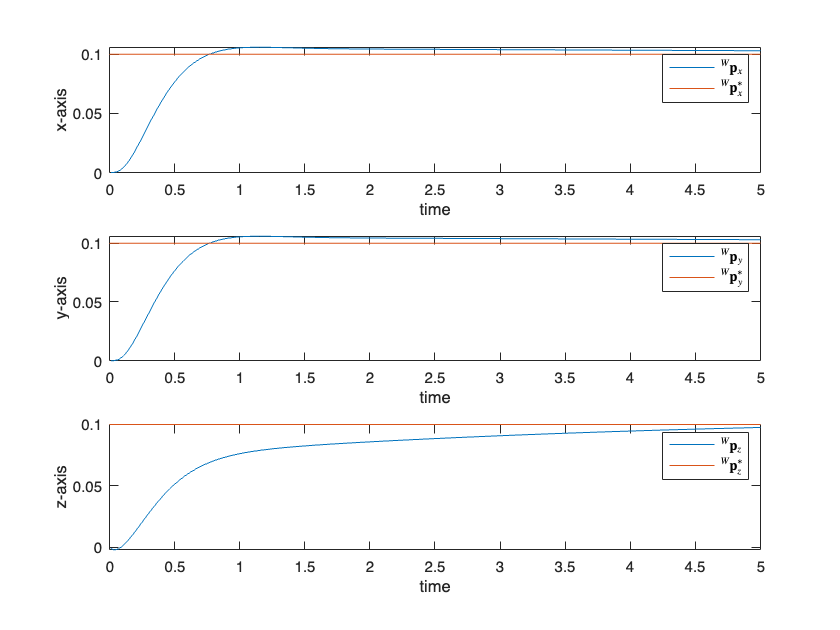


figure(3),clf
subplot(3,1,1),plot(time,p_array(1,:)),hold on, line([0 simTime],[p_des(1) p_des(1)])
xlabel('time'),ylabel('x-axis'),legend('${^W{\bf p}_x}$','${^W{\bf p}^*_x}$',"interpreter","latex")
subplot(3,1,2),plot(time,p_array(2,:)),hold on, line([0 simTime],[p_des(2) p_des(2)])
xlabel('time'),ylabel('y-axis'),legend('${^W{\bf p}_y}$','${^W{\bf p}_y^*}$',"interpreter","latex")
subplot(3,1,3),plot(time,p_array(3,:)),hold on, line([0 simTime],[p_des(3) p_des(3)])
xlabel('time'),ylabel('z-axis'),legend('${^W{\bf p}_z}$','${^W{\bf p}_z^*}$',"interpreter","latex")